# 1. aet2-Klausur  2Ea/2Eb  vom  26.3.2014

## 1. Bestimmen Sie die das Thevenin-Ersatzschaltbild bezüglich der Klemmen 1-1´ 

für die Frequenz von f  1MHz . 

format shorteng; clear all; clc
I1_=0.3*exp(j*deg2rad(65));
U2_=-(15-35*j);
f=1e6; w=2*pi*f;
L1=22e-6;   Zl1_=j*w*L1;
R1=100;     
C1=2e-9;    Zc1_=1/(j*w*C1);
R2=250;
C2=820;     Zc2_=1/(j*w*C2);

Zq_= par( (par(Zl1_, R1)+Zc1_), R2, Zc2_)

Zq_ =    613.8800e-024 -194.0914e-012i



% Iq zu Uq
Zrl1_=par(Zl1_, R1);
Ue1_=I1_*Zrl1_;
Zrlc_=Zrl1_+Zc1_;
Ue12_=Ue1_+U2_;

% what?



## 2. Bei einer unbekannten Impedanz werden bei einer Frequenz von 50 Hz 

ein Strom von 0.13 A und eine Spannung von 230 V gemessen. Der Minimalwert der Momentanleistung beträgt  -20 W. Bestimmen Sie alle Ersatznetzwerke mit zwei Elementen, die für diese Impedanz möglich sind. 

 (Numerische Werte der Elemente angeben). 

clear all;
f=50;
w=2*pi*f;
I=0.13;
U=230;
pmin=-20;
cosphi=pmin/(U*I)+1;
% U*I*(cosphi-1)
phi=acos(cosphi); phid=acosd(cosphi)

phid =     70.6642e+000


pmax=U*I*(cosphi+1)

pmax =     39.8000e+000


P=1/2*(pmax+pmin)

P =      9.9000e+000



U_=U*exp(j*0);
I_=I*exp(j*phi); % +/-phi   ---> I_'
S_=U_*I_';
Z_=S_/(abs(I_)^2)

Z_ =    585.7988e+000 -  1.6694e+003i


Z_=((U^2)/S_)'

Z_ =    585.7988e+000 -  1.6694e+003i


Y_=1/Z_;

1. R + L

"R + L"

ans = "R + L"

%Rs=(U^2)/P
Rs=real(Z_)

Rs =    585.7988e+000


Xls=imag(Z_');
Ls=Xls/(w)

Ls =      5.3140e+000


Zrsl_=Rs+j*w*Ls;

2. R + C

"R + C"

ans = "R + C"

Rs=Rs

Rs =    585.7988e+000


Xcs=imag(Z_);
Cs=1/(w*Xls)

Cs =      1.9067e-006


Zrsc_=Rs+1/(j*w*Cs);

3. R || L

"R || L"

ans = "R || L"

Gp=real(Y_);
Rp=1/Gp

Rp =      5.3434e+003


Blp=imag(Y_);
Lp=1/(w*Blp)

Lp =      5.9683e+000


Zrpl_=par(Rp, j*w*Lp);

4. R || C

"R || C"

ans = "R || C"

Rp=1/Gp

Rp =      5.3434e+003


Bcp=Blp;
Cp=Bcp/(w)

Cp =      1.6977e-006


Zrpc_=par(Rp, 1/(j*w*Cp));

Kontrolle

Srpc_ = U^2/Zrpc_'

Srpc_ =      9.9000e+000 - 28.2135e+000i


Srpl_ = U^2/Zrpl_'

Srpl_ =      9.9000e+000 + 28.2135e+000i


Srsc_ = U^2/Zrsc_'

Srsc_ =      9.9000e+000 - 28.2135e+000i


Srsl_ = U^2/Zrsl_'

Srsl_ =      9.9000e+000 + 28.2135e+000i



Irpc = abs(U_/Zrpc_) % = 130mA stimmt

Irpc =    130.0000e-003


Irpl = abs(U_/Zrpl_) % = 130mA stimmt

Irpl =    130.0000e-003


Irsc = abs(U_/Zrsc_) % = 130mA stimmt

Irsc =    130.0000e-003


Irsl = abs(U_/Zrsl_) % = 130mA stimmt

Irsl =    130.0000e-003


## 3. Das skizzierte Netzwerk nimmt bei einer Frequenz von 1 MHz eine Leistung von P = 6.7 W auf. 

- Berechnen Sie die Werte von L und C. 

clear all;
R=470;
U=110;
I=75e-3;
P=6.7;
f=1e6;
w=2*pi*f;

Ur=sqrt(P*R);
Ir=sqrt(P/R);
Il=I-Ir

Il =    -44.3956e-003


% What?

## 4. Die Spannung u(t) wird am skizzierten Netzwerk angelegt: 

 u(t)  35cos(t 1),   2 50

%%
clear all;
U_=35/sqrt(2)*exp(j*1);
f=50; w=2*pi*f; T=1/f;
R1=15;
R2=82;
C=60e-6;    Zc_=1/(j*w*C);
L=50e-3;    Zl_=j*w*L;


Z_=R1+par(Zl_, (Zc_+R2));
I_=U_/Z_;
I=sqrt(2)*abs(I_)

I =      1.4413e+000


phi_i=rad2deg(angle(I_))

phi_i =     13.3790e+000



t=linspace(0, T,1e3);
u=35.*cos(w*t+1);
i=I.*cos(w*t+deg2rad(phi_i));

p=u.*i;
hold off
plot(t,p);
pmax=max(p)

pmax =     43.3932e+000


pmin=min(p)

pmin =     -7.0537e+000


P=1/2*(pmax+pmin)

P =     18.1698e+000


% p(t) = U*I*[cos(2wt+phiU+phiI) + cos(deltaphi)]
dphi=angle(U_)-angle(I_);
p2=abs(U_).*abs(I_).*(cos(2*w*t+angle(U_)+angle(I_))+cos(dphi));

hold on
plot(t, p2)     % stimmt

syms t000
t0lsg=solve(abs(U_)*abs(I_)*(cos(2*w*t000+angle(U_)+angle(I_))+cos(dphi)) == 0);
% die Lösung ist t0(1)
t0=double(t0lsg(2))+T/2

t0 =      1.8169e-003


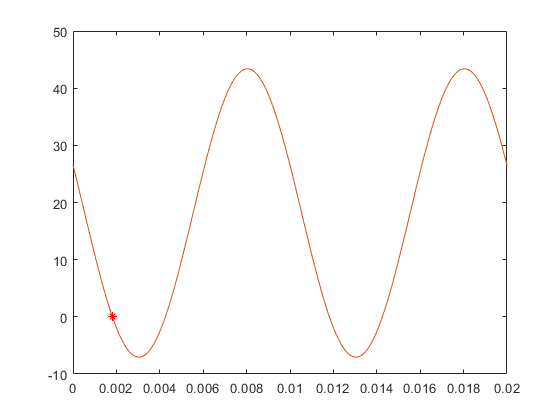


%t0=(angle(I_)/w)
plot(t0,0,'r*')

## 5. Berechnen Sie von den folgenden Frequenzgängen je Betrag und Phase in Funktion von ω. 